# Cviceni 6

## UKOL  k zamysleni ze cviceni 5

Na obrázek a.png jsou postupně aplikovány čtvercové průměrovací filtry o velikosti 30 (a), 34 (b) a 45 (c). Svislé čáry vlevo dole jsou na obrázcích (a) a (c) rozmazané, ale existuje mezi nimi jasný přechod. U obrázku (b)  znatelné nejsou navzdory tomu, že je velikost průměrovací masky znatelně menší, než v případě (b). Jak je to možné?

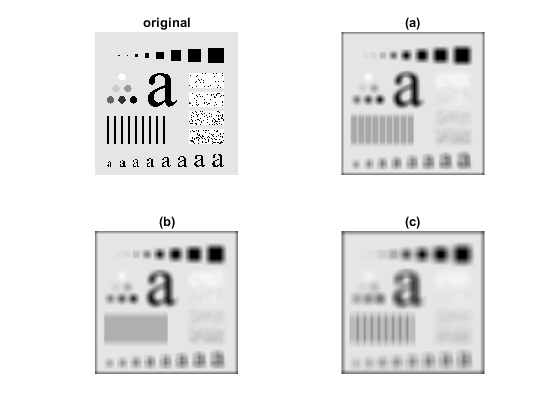

I = imread('a.png');

a = 30;
b = 34;
c = 45;

Ha = fspecial('average',[a,a]);
Hb = fspecial('average',[b,b]);
Hc = fspecial('average',[c,c]);
A = imfilter(I,Ha);
B = imfilter(I,Hb);
C = imfilter(I,Hc);

figure,
subplot(2,2,1), imshow(I);
title('original');
subplot(2,2,2), imshow(A);
title('(a)');
subplot(2,2,3), imshow(B);
title('(b)');
subplot(2,2,4), imshow(C);
title('(c)');

## Soucet funkci

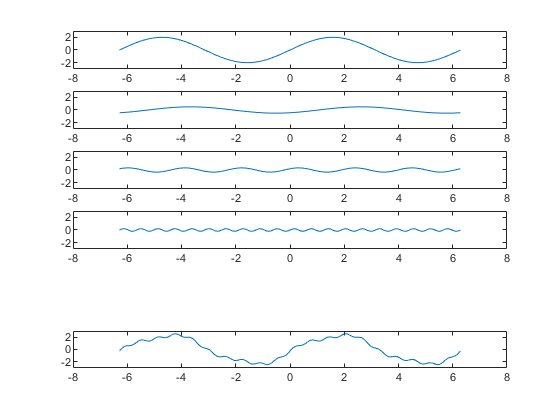

n = 300; % pocet bodu

% vytvoření vektoru o n hodnotách pravidelně rozmístěné mezi -2pi a 2pi
x = linspace(-2*pi,2*pi,n)';

% jednotlive funkce
y1s = 2*sin(x);
y2s = sin(x-pi/3)/2;
y3s = sin(3*x+pi/5)/3;
y4s = sin(10*x)/5;

y1c = 2*cos(x);
y2c = cos(x-pi/3)/2;
y3c = cos(3*x+pi/5)/3;
y4c = cos(10*x)/5;

figure,
subplot(6,1,1), plot(x,y1s);
ylim([-3,3]);
subplot(6,1,2), plot(x,y2s);
ylim([-3,3]);
subplot(6,1,3), plot(x,y3s);
ylim([-3,3]);
subplot(6,1,4), plot(x,y4s);
ylim([-3,3]);
subplot(6,1,6), plot(x,y1s+y2s+y3s+y4s);
ylim([-3,3]);

### Animace

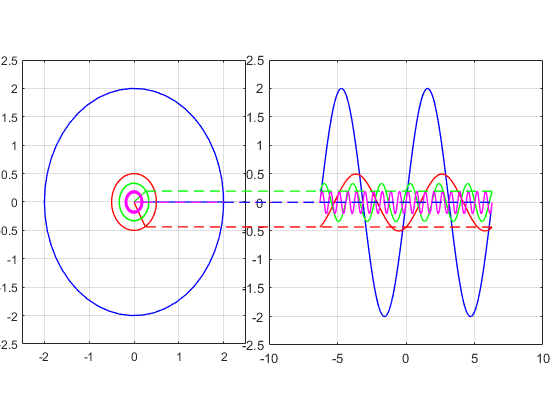

nt = 50; %pocet bodu na kruznici
theta  =linspace(-pi,pi,nt)';   % diskretni body na kruznici

% Kruznice
kx1 = 2*cos(theta);
ky1 = 2*sin(theta);

kx2 = cos(theta-pi/3)/2;
ky2 = sin(theta-pi/3)/2;

kx3 = cos(3*theta+pi/5)/3;
ky3 = sin(3*theta+pi/5)/3;

kx4 = cos(10*theta)/5;
ky4 = sin(10*theta)/5;

Lx=length(x);
Lw=1; %sirka cary
Fs=12;

for i=1:Lx

 f1=figure (2); clf;

 sp1=subplot(1,2,1);
 %  Funkce 1
 plot(kx1,ky1,'LineWidth',Lw,'Color','b'); hold on; grid on;
 line([0 y1c(i)],[0 y1s(i)],'Color','b','LineWidth',Lw,'LineSmoothing','on');

 set(sp1,'Position',[0.0400    0.1800    0.4    0.677]);
 xlim([-2.5 2.5]); ylim([-2.5 2.5])

 line(y1c(i),y1s(i),10,'LineStyle','-','MarkerSize',8,'MarkerFaceColor','b','color','b')
    
 [xf1, yf1] = ds2nfu(sp1,y1c(i),y1s(i));
    
 %  Funkce 2
 plot(kx2,ky2,'LineWidth',Lw,'Color','r'); hold on;
 line([0 y2c(i)],[0 y2s(i)],'Color','r','LineWidth',Lw,'LineSmoothing','on');
 line(y2c(i),y2s(i),10,'LineStyle','-','MarkerSize',8,'MarkerFaceColor','r','color','r')
    
 [xf2, yf2] = ds2nfu(sp1,y2c(i),y2s(i));

 %  Funkce 3
 plot(kx3,ky3,'LineWidth',Lw,'Color','g'); hold on;
 line([0 y3c(i)],[0 y3s(i)],'Color','g','LineWidth',Lw,'LineSmoothing','on');
 line(y3c(i),y3s(i),10,'LineStyle','-','MarkerSize',8,'MarkerFaceColor','g','color','g')
    
 [xf3, yf3] = ds2nfu(sp1,y3c(i),y3s(i));
    
 %  Funkce 4
 plot(kx4,ky4,'LineWidth',Lw,'Color','m'); hold on;
 line([0 y4c(i)],[0 y4s(i)],'Color','m','LineWidth',Lw,'LineSmoothing','on');
 line(y4c(i),y4s(i),10,'LineStyle','-','MarkerSize',8,'MarkerFaceColor','m','color','m')
    
 [xf4, yf4] = ds2nfu(sp1,y4c(i),y4s(i));
  
 sp2=subplot(1,2,2);
 %  Funkce 1
    
 plot(x(1:i),y1s(1:i),'LineWidth',Lw,'Color','b'); hold on; grid on;
 ylim([-2.5 2.5]); xlim([-10 10])
 set(sp2,'Position',[0.48    0.178200    0.49    0.680]);
    
 [xg1, yg1] = ds2nfu(x(i),y1s(i));
 annotation('line',[xf1 xg1],[yf1 yg1],'color','b','LineStyle','--','LineWidth',Lw);

 % Funkce 2
 plot(sp2,x(1:i),y2s(1:i),'g','LineWidth',Lw,'Color','r'); hold on; grid on;
    
 [xg2, yg2] = ds2nfu(x(i),y2s(i));
 annotation('line',[xf2 xg2],[yf2 yg2],'color','r','LineStyle','--','LineWidth',Lw);

 % Funkce 3
 plot(sp2,x(1:i),y3s(1:i),'g','LineWidth',Lw,'Color','g'); hold on; grid on;
    
 [xg3, yg3] = ds2nfu(x(i),y3s(i));
 annotation('line',[xf3 xg3],[yf3 yg3],'color','g','LineStyle','--','LineWidth',Lw);
    
 % Funkce 4
 plot(sp2,x(1:i),y4s(1:i),'g','LineWidth',Lw,'Color','m'); hold on; grid on;
    
 [xg4, yg4] = ds2nfu(x(i),y4s(i));
 annotation('line',[xf4 xg4],[yf4 yg4],'color','m','LineStyle','--','LineWidth',Lw);
    
 pause(0.01);
end

### Animace dohromady

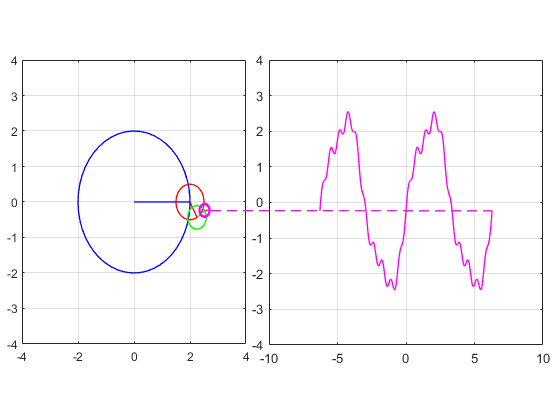

for i=1:length(x)
 f1=figure (2); clf;

 sp1=subplot(1,2,1);
 %  Funkce 1
 plot(kx1,ky1,'LineWidth',Lw,'Color','b'); hold on; grid on;
 line([0 y1c(i)],[0 y1s(i)],'Color','b','LineWidth',Lw,'LineSmoothing','on');

 set(sp1,'Position',[0.0400    0.1800    0.4    0.677]);
 xlim([-4 4]); ylim([-4 4])

 line(y1c(i),y1s(i),10,'LineStyle','-','MarkerSize',8,'MarkerFaceColor','b','color','b')
    
 %  Funkce 2
 plot(kx2+y1c(i),ky2+y1s(i),'LineWidth',Lw,'Color','r'); hold on;
 line(y1c(i)+[0 y2c(i)],y1s(i)+[0 y2s(i)],'Color','r','LineWidth',Lw,'LineSmoothing','on');
    
 %  Funkce 3
 plot(kx3+y1c(i)+y2c(i),ky3+y1s(i)+y2s(i),'LineWidth',Lw,'Color','g'); hold on;
 line(y1c(i)+y2c(i)+[0 y3c(i)],y1s(i)+y2s(i)+[0 y3s(i)],'Color','g','LineWidth',Lw, ...
     'LineSmoothing','on');
    
 %  Funkce 4
 plot(kx4+y1c(i)+y2c(i)+y3c(i),ky4+y1s(i)+y2s(i)+y3s(i),'LineWidth',Lw,'Color','m'); 
 hold on;
 line(y1c(i)+y2c(i)+y3c(i)+[0 y4c(i)],y1s(i)+y2s(i)+y3s(i)+[0 y4s(i)],'Color','m',...
     'LineWidth',Lw,'LineSmoothing','on');
  
 [xf4, yf4] = ds2nfu(y1c(i)+y2c(i)+y3c(i)+y4c(i),y1s(i)+y2s(i)+y3s(i)+y4s(i));
    
 sp2=subplot(1,2,2);
 %  dohromady
    
 plot(x(1:i),y1s(1:i)+y2s(1:i)+y3s(1:i)+y4s(1:i),'LineWidth',Lw,'Color','m');
 hold on; grid on;  
    
 ylim([-4 4]); xlim([-10 10])
 set(sp2,'Position',[0.48    0.178200    0.49    0.680]);
    
 [xgt, ygt] = ds2nfu(x(i),y1s(i)+y2s(i)+y3s(i)+y4s(i)); 
 annotation('line',[xf4 xgt],[yf4 ygt],'color','m','LineStyle','--','LineWidth',Lw);
    
 pause(0.01);
end

## Fourierova řada

Funkce: Fseries.m and Fseriesval.m

y = a_0 / 2 + Sum_k [ a_k cos(kx) + b_k sin(kx) ]

### Priklad 1

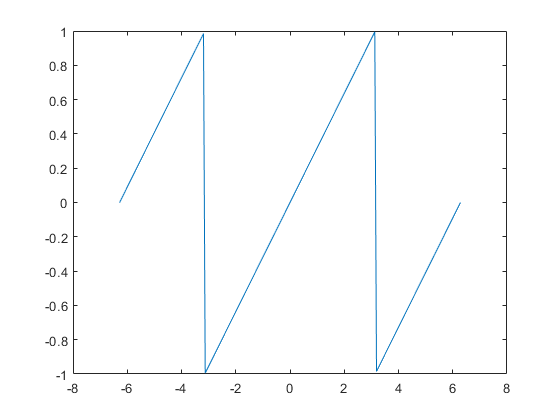

% Generovani dat

% vytvoreni vektoru o 50 hodnotach pravidelne rozmistene mezi -2pi a 2pi
x = linspace(-2*pi,2*pi,200)'; 
% vypocet funkcnich hodnot pomci funkce sawtooth
y = sawtooth(x + pi); 

% alternativni vypocet bez pouziti funkce sawtooth
%y = mod(x + pi,2*pi) - pi;

figure, plot(x,y);

#### Rozvoj pomoci sinu a cosinu

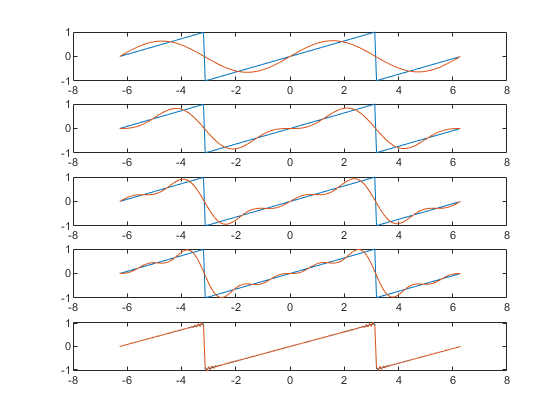

% rady
n = [2, 4, 6, 8, 90];

figure,
% pro vsechny rady spocitame rozvoj pomoci Fseries
for i = 1 : size(n,2)
    [~,b,yfit] = Fseries(x,y,n(i));
    subplot(size(n,2),1,i)
    plot(x,y,x,yfit);    
end

#### Animace

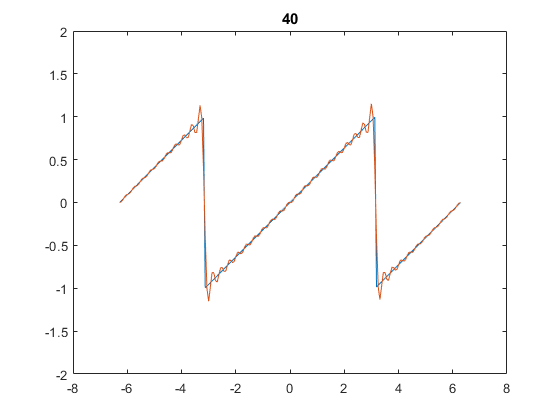

% pro vsechny rady spocitame rozvoj pomoci Fseries
figure,
for i = 2 : 2 : 40
    [~,b,yfit] = Fseries(x,y,i);
    pause(0.3);
    plot(x,y,x,yfit);   
    title(num2str(i));
    ylim([-2,2]);
end

### Priklad 2

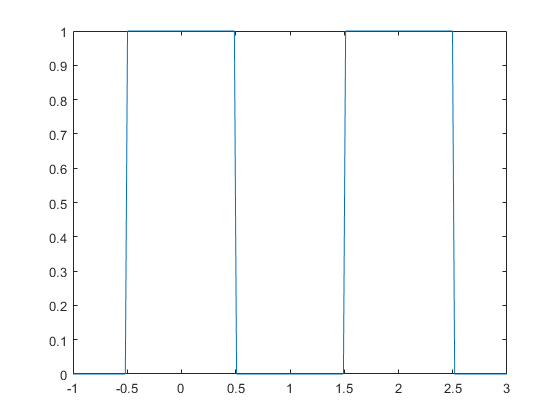

% Generovani dat
x = linspace(-1,3,200)'; 
y =  double(or(and(x < 2.5, x >= 1.5),and(x< 0.5, x >= -0.5)));% vypocet funkcnich hodnot 
figure, plot(x,y);

#### Rozvoj pomoci sinu a cosinu

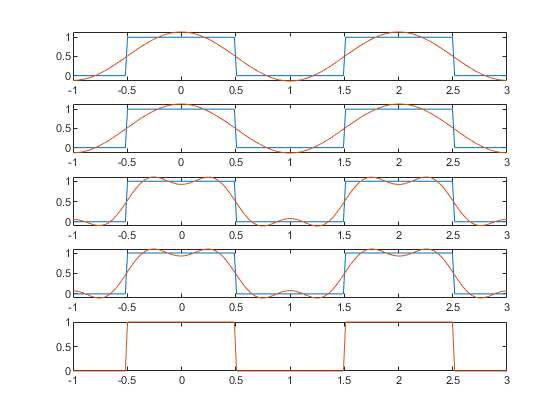

% rady 
n = [2, 4, 6, 8, 99];

figure,
% pro vsechny rady spocitame rozvoj pomoci Fseries
for i = 1 : size(n,2)
    [~,b,yfit] = Fseries(x,y,n(i));
    subplot(size(n,2),1,i)
    plot(x,y,x,yfit);    
end

#### Animace

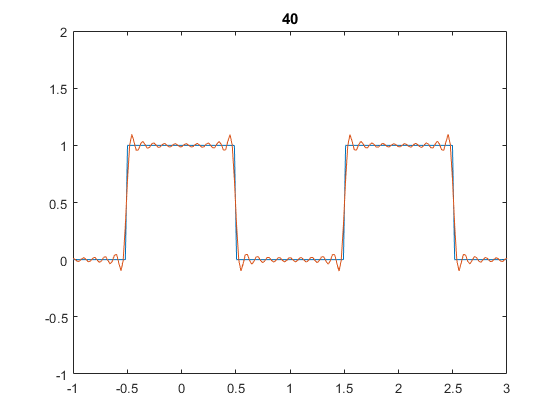

figure,
for i = 2 : 2 : 40
    [~,b,yfit] = Fseries(x,y,i);
    pause(0.3);
    plot(x,y,x,yfit);   
    title(num2str(i));
    ylim([-1,2]);
end

## Frekvencni domena

### Vytvoření jednoduchého obrázku

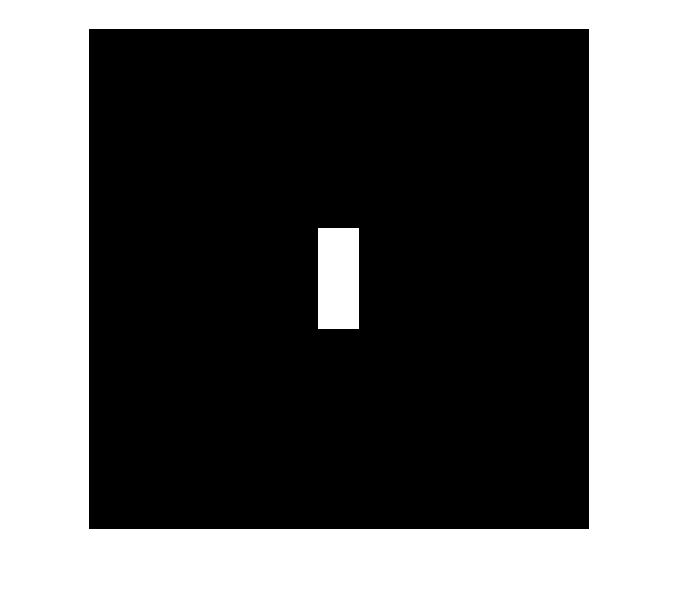

f = zeros(500);
f(200:300,230:270)=1;
figure, imshow(f);

### Fourierovo spektrum

Převod do frekvencni domeny - funkce fft2 (Fast fourier transform)

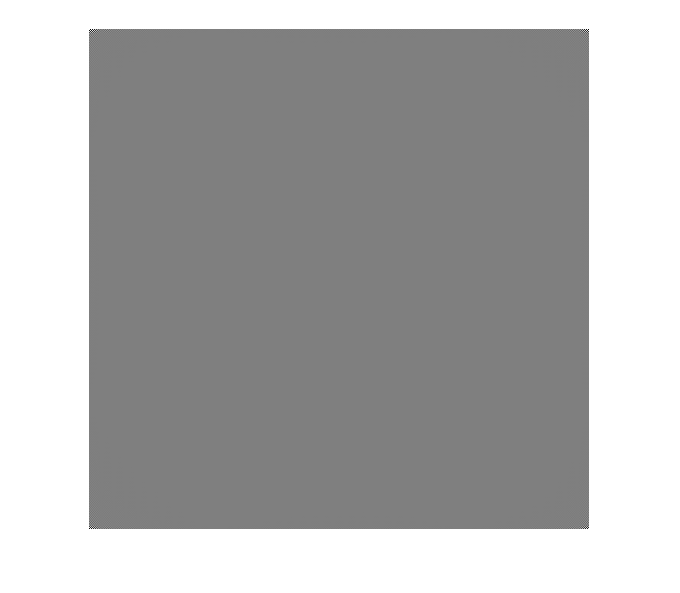

F = fft2(f);
figure('name','Frekvencni domena'), imshow(F,[]);

### DC koeficient 

dc_koef = F(1,1);
display(dc_koef);

dc_koef = 4141


[m,n]=size(F);

% DC koef. vydeleny poctem pixelu
dc_koef_norm = F(1,1)/(m*n);
display(dc_koef_norm);

dc_koef_norm = 0.0166


% Prumerna intenzita v obrazku
prum_int = sum(sum(f))/(m*n);
display(prum_int);

prum_int = 0.0166

### Spektrum 

ziskame pomoci absolutni hodnoty z vysledku

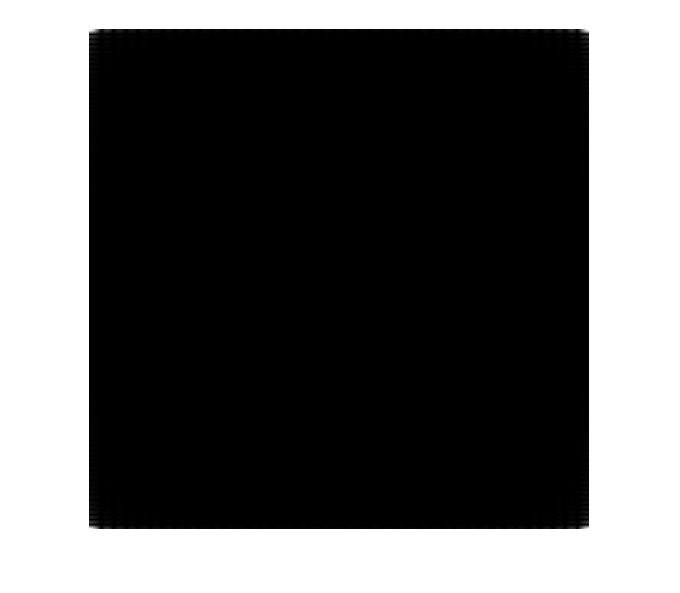

S = abs(F);
figure('name','Foufierovo spektrum'), imshow(S,[]);

### Centrovane fourierovo spektrum

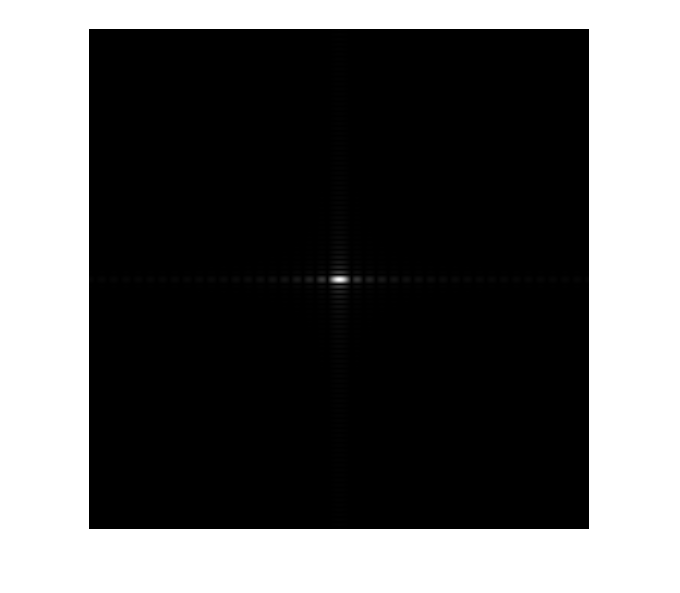

Sc = fftshift(S);
figure('name','Centrovane foufierovo spektrum'), imshow(Sc,[]);

#### Funkce fftshift

Provede se posun o pul periody doprava a dolu (tedy jako by se prehodil 1. a 4. kvadrant a 2. a 3).

a = [1 2; 
     3 4];
fftshift(a)

ans =      4     3
     2     1


### Fourierovo spektum logaritmicka transformace

maximalni = max(max(Sc));
display(maximalni);

maximalni = 4141

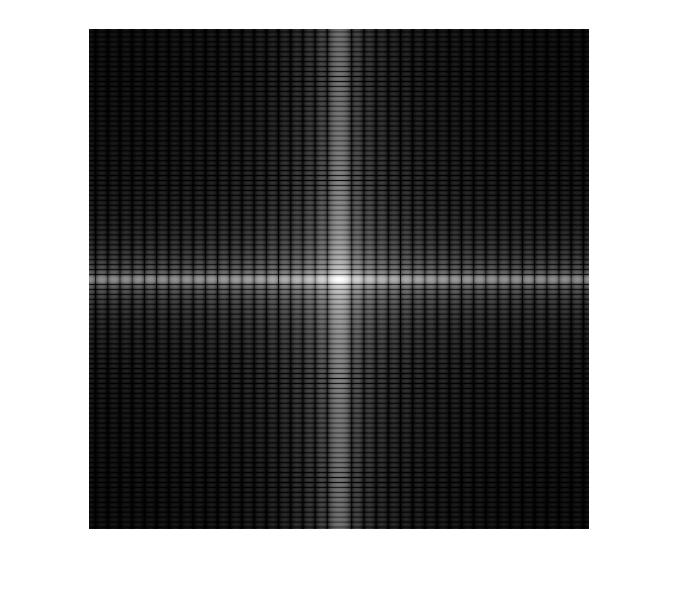


Scl = log(1+Sc);
figure('name','Centrovane foufierovo spektrum - logaritmicka transformace'), imshow(Scl,[]);

### Necentrovane fourierovo spektrum

S1 = ifftshift(Sc);
figure('name','Foufierovo spektrum'), imshow(S1,[]);

#### Funkce ifftshift

M = [1 2 3; 4 5 6; 7 8 9];
M2 = fftshift(M);

fftshift(M2)

ans =      5     6     4
     8     9     7
     2     3     1


ifftshift(M2)

ans =      1     2     3
     4     5     6
     7     8     9


### Fáze

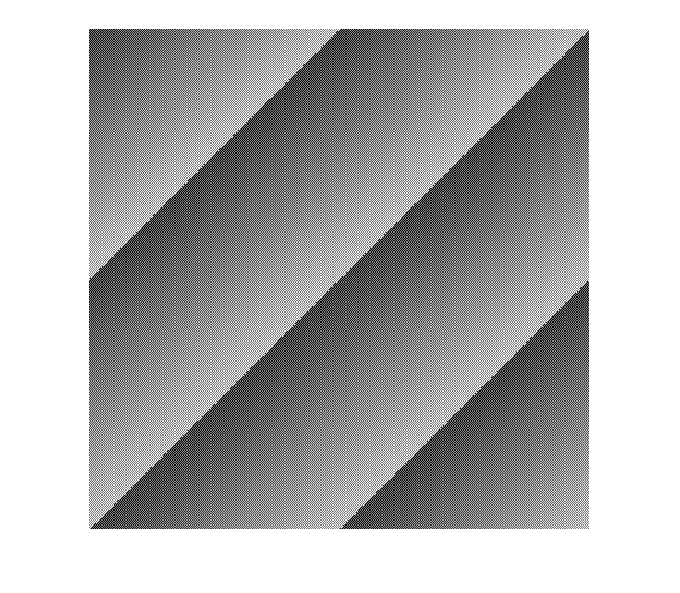

R = real(F);
I = imag(F);
phi = atan2(I,R);
%aphi = angle(F);

figure, imshow(phi,[]);

## Ukol 1

Vytvorte dva stejne velke cernobile obrazky. Obrazky maja cerne pozadi a obsahuji stejne velky bily obdelnik jen na jinem miste. Porovnejte spektra a faze techto obrazku.

### Prevod do prostorove domeny

f = ifft2(F);
f = real(f);

figure('name','Prostorova domena'), imshow(f,[]);

## Filtrovani ve frekvencni domene

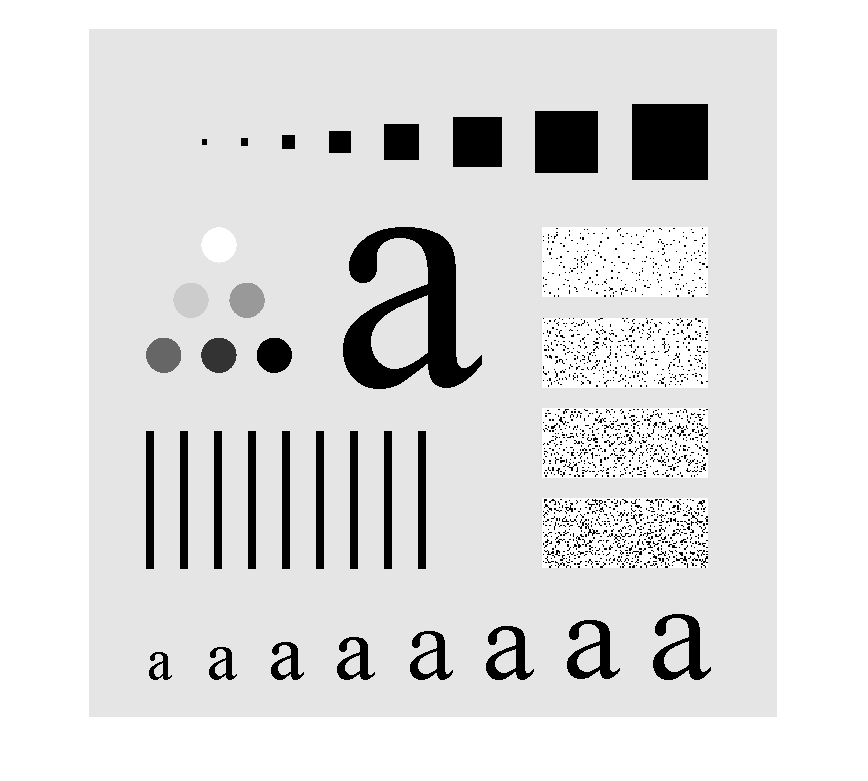

f=rgb2gray(imread('a.png'));
f = double(f);
figure, imshow(f,[]);

### Idealni LP filtr

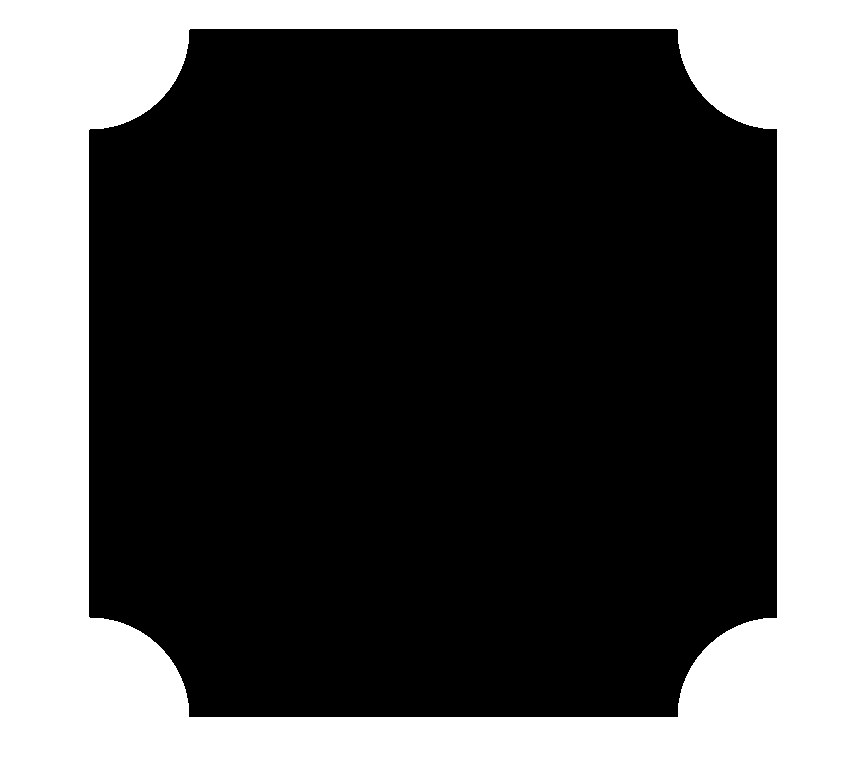

[m,n] = size(f);

r=100;
H_ideal = lpfilter('ideal' , m, n, r) ;

figure, imshow(H_ideal,[]);

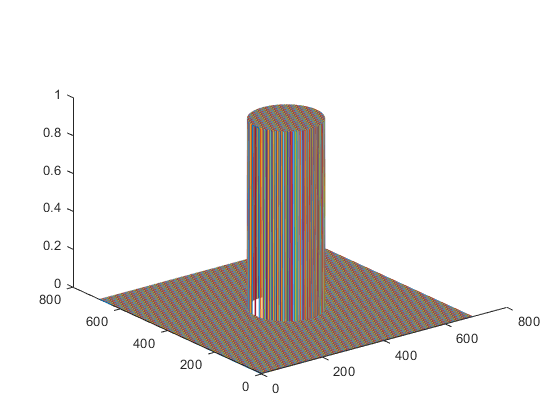

[xx,yy] = meshgrid(1:m,1:n);
figure, plot3(xx,yy,fftshift(H_ideal));

### Butterworth LP filtr

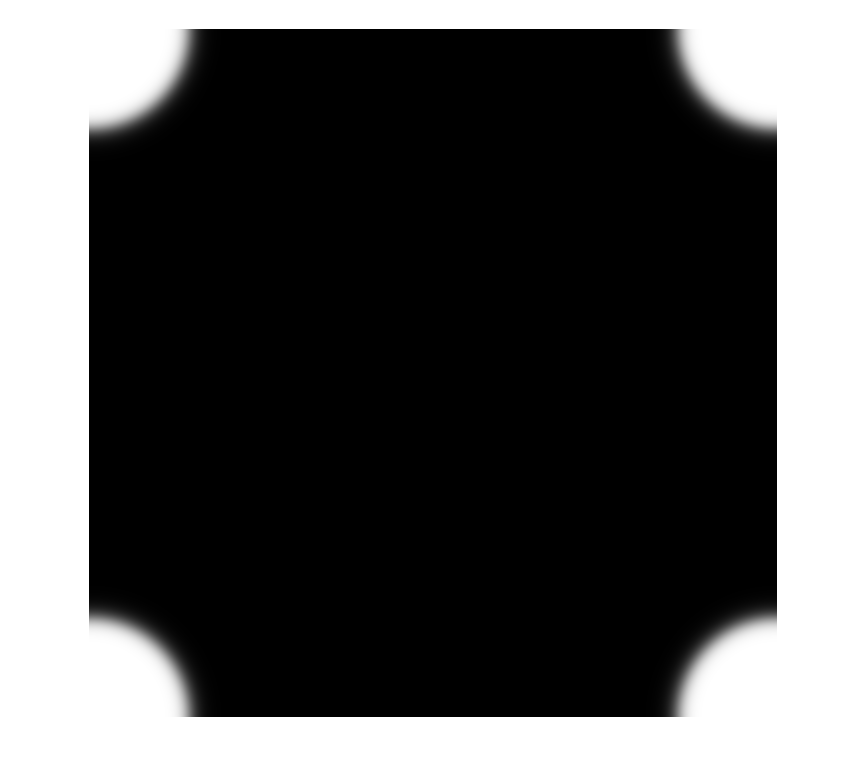

[m,n] = size(f);

r=100;
rad=10;
H_btw = lpfilter('btw' , m, n, r,rad) ;

figure, imshow(H_btw,[]);

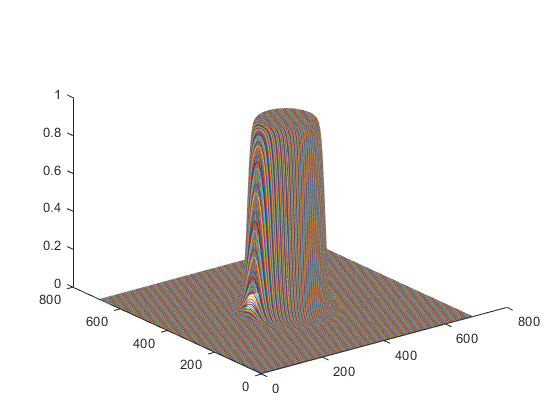

[xx,yy] = meshgrid(1:m,1:n);
figure, plot3(xx,yy,fftshift(H_btw));

### Gauss LP filtr

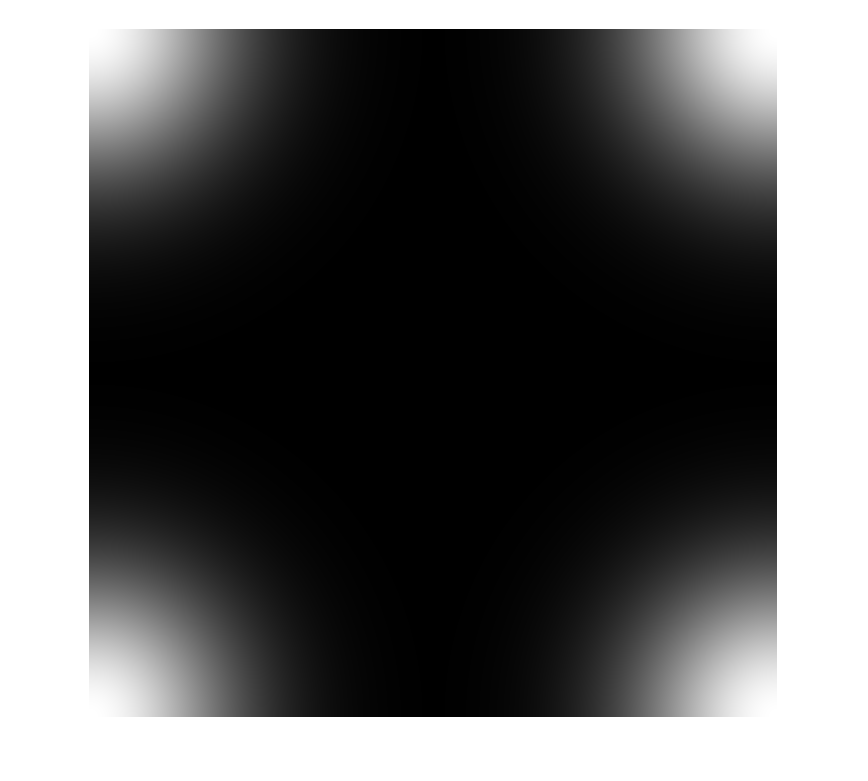

[m,n] = size(f);

r=100;
H_gauss = lpfilter('gaussian' , m, n, r) ;

figure, imshow(H_gauss,[]);

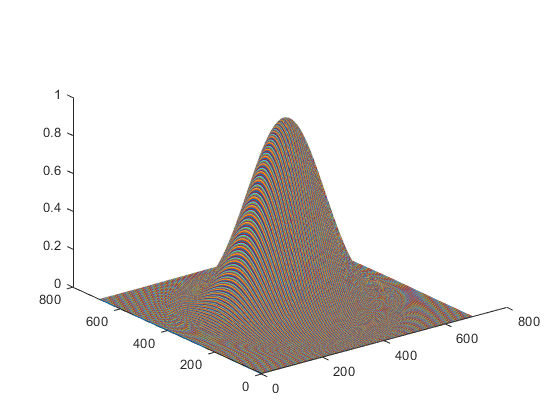

[xx,yy] = meshgrid(1:m,1:n);
figure, plot3(xx,yy,fftshift(H_gauss));

## Ukol 2

Vytvorte idealni, butterworth a gaussuv high pass filtr a vyzkousejte jeho aplikaci na obrazek (viz nize). High pass filtr (HPF) ziskate z low pass filteru (LPF): HPF = 1 - LPF

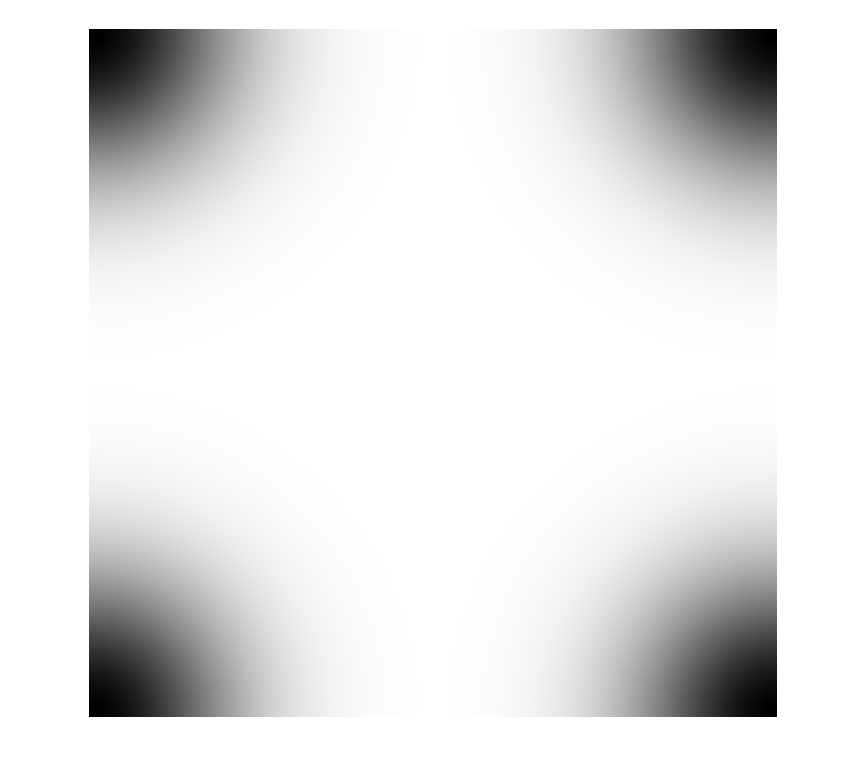

% TO DO funkce hpfilter

H_ideal_hp = hpfilter('ideal' , m, n, r) ;
H_btw_hp = hpfilter('btw' , m, n, r) ;
H_gauss_hp = hpfilter('gaussian' , m, n, r) ;

figure, imshow(H_gauss_hp,[]);

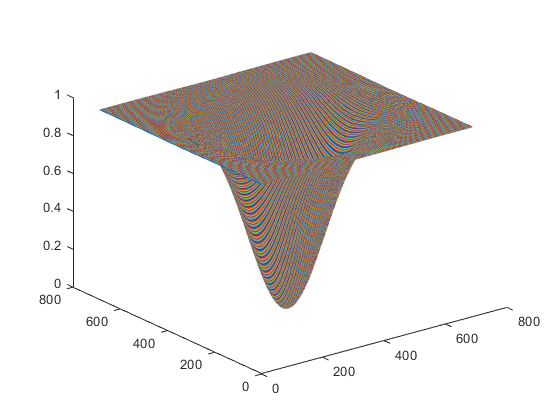


[xx,yy] = meshgrid(1:m,1:n);
figure, plot3(xx,yy,fftshift(H_gauss_hp));

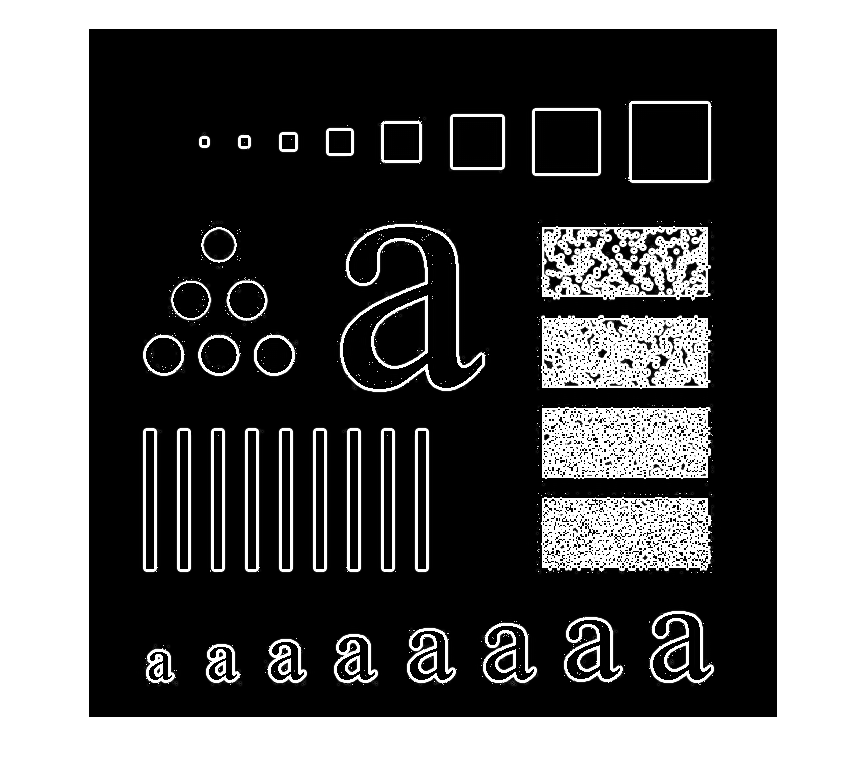


F = fft2(f);
G = H_gauss_hp.*F;f2=ifft2(G);
f2 = real(f2);

figure,imshow(f2);

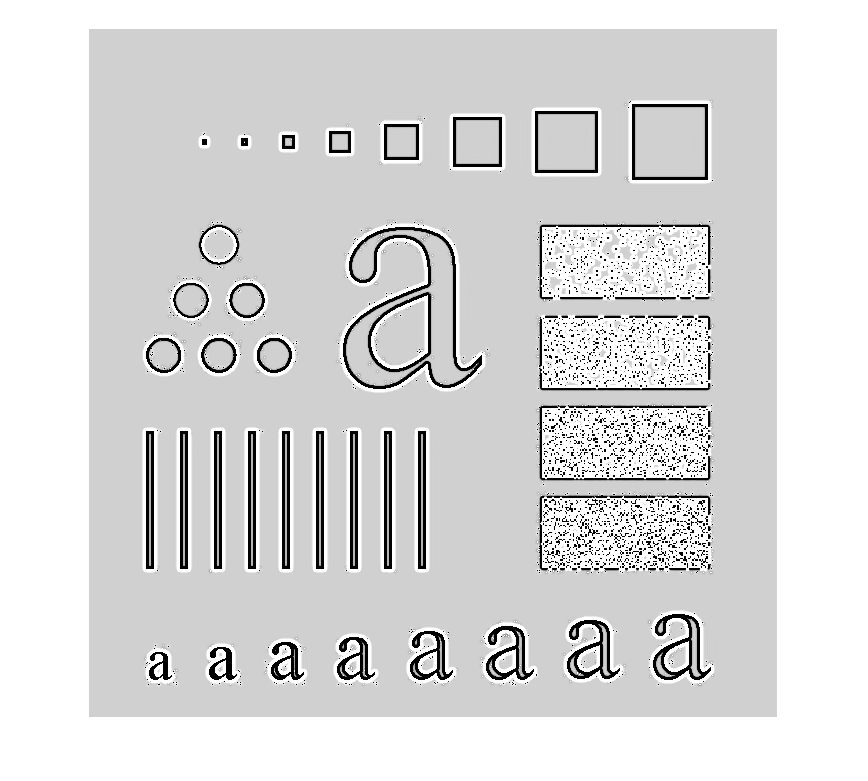


% Odstranili jsme DC koeficient, tedy i informaci o prumerne hodnote v
% obrazku.

f3 = (F(1,1)/(m*n))/255 + f2;
figure,imshow(f3);

### Aplikace filtru - ideal

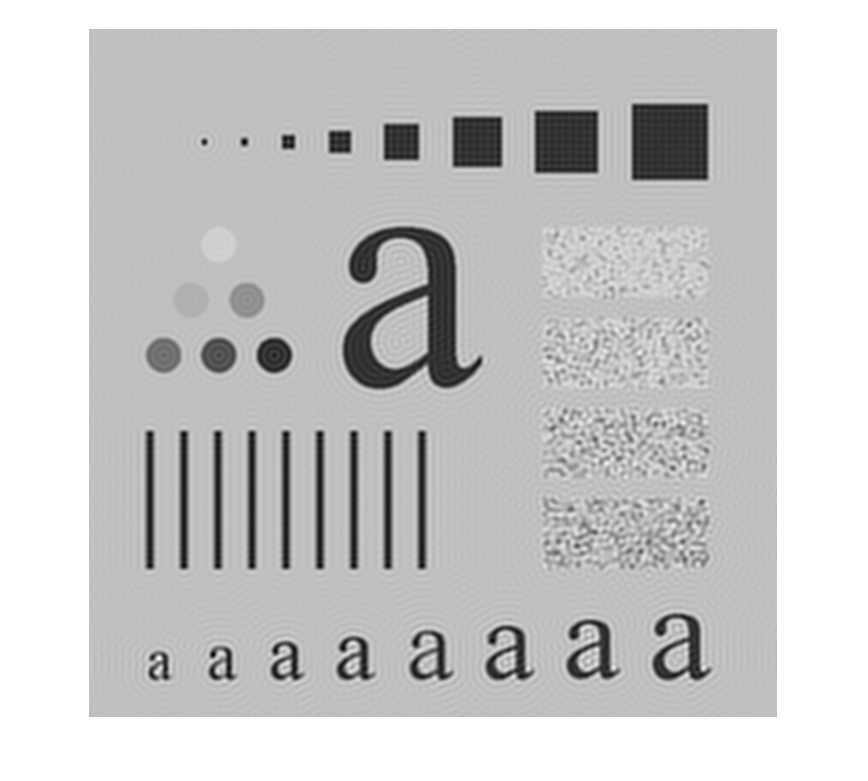

F = fft2(f);
% fitrovani
G = H_ideal.*F;

% prevod zpet
f2=ifft2(G);

f2 = real(f2);

figure,imshow(f2,[]);

### Aplikace filtru - butterworth

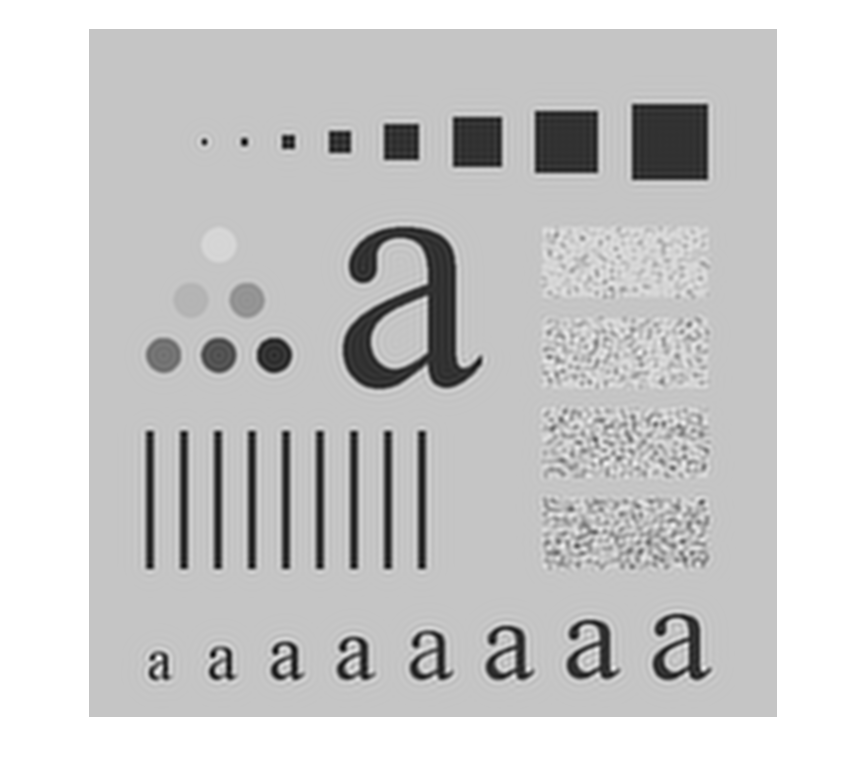

F = fft2(f);
% fitrovani
G = H_btw.*F;

% prevod zpet
f2=ifft2(G);

f2 = real(f2);

figure,imshow(f2,[]);

### Aplikace filtru - gauss

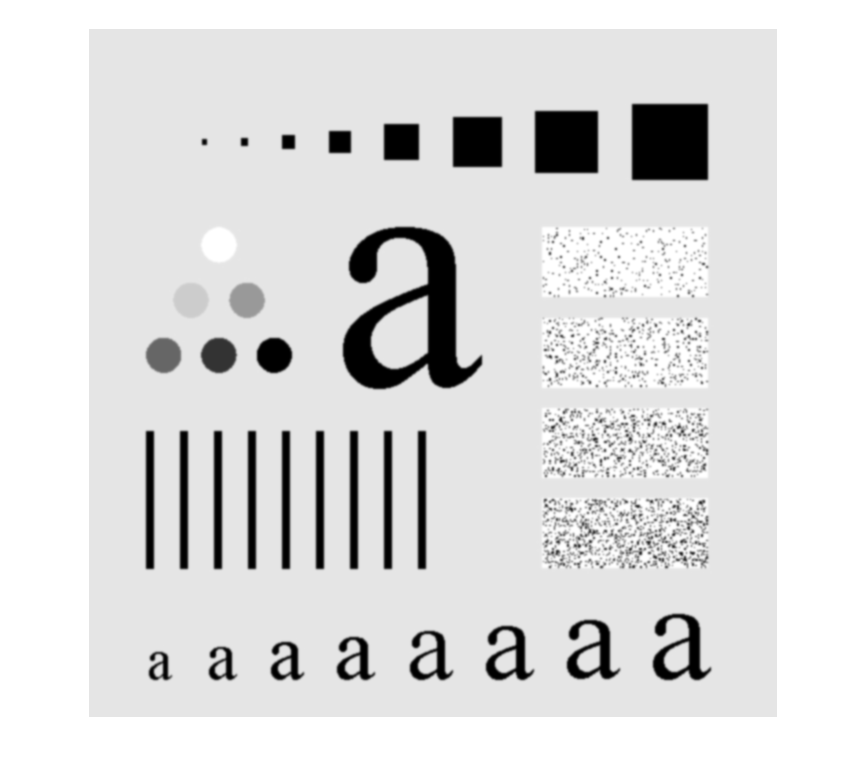


F = fft2(f);
% fitrovani
G = H_gauss.*F;

% prevod zpet
f2=ifft2(G);

f2 = real(f2);

figure,imshow(f2,[]);

### Vytvoreni filtru z filtru v prostorove domene

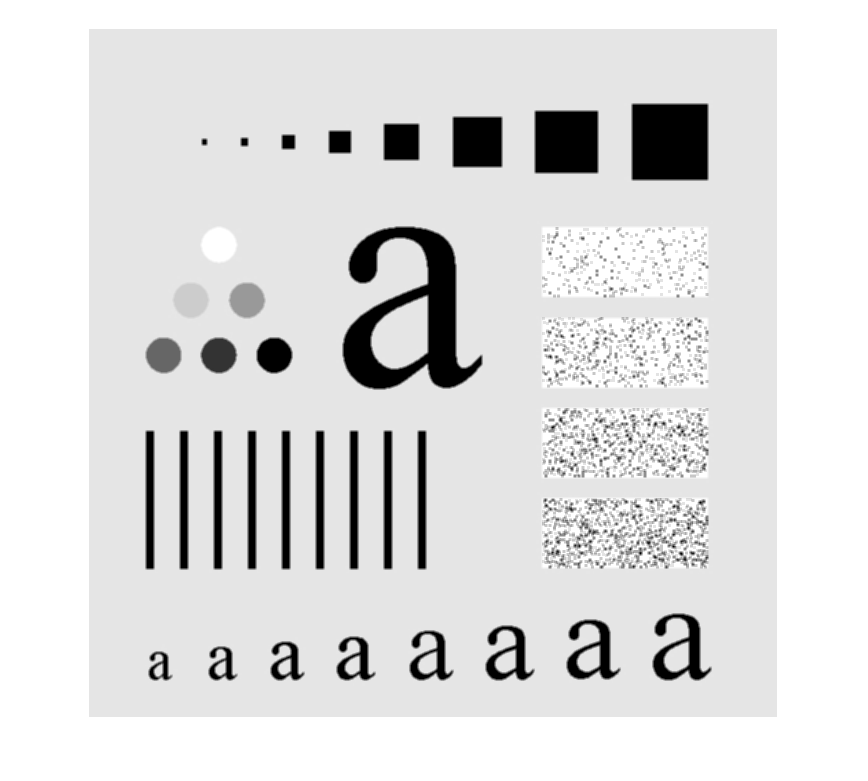

% konvolucni maska
h = (1/9) * ones(3);

F = fft2(f);

% vytvoreni masky ve frekvencni domene o velikosti stejne jako je obrazek
H = freqz2(h, m, n);

H1 = ifftshift(H);

% fitrovani
G = H1.*F;

% prevod zpet
f2=ifft2(G);

f2 = real(f2);

figure,imshow(f2,[]);

## Ukol 3

Vytvorte pomocí funkce freqz2 nejaky ostricí filtr a aplikujte ho na obrazek.

## Porovnani filtrovani v domenach

f=imread('lenagraysum.bmp');
[m,n] = size(f);
f = double(f);

h = 1/100*ones(10);
H = freqz2(h, m, n);
H1 = ifftshift(H);

### Prostorova

tic();
gp = imfilter(f,h,'conv','same');
toc()

Elapsed time is 0.015484 seconds.


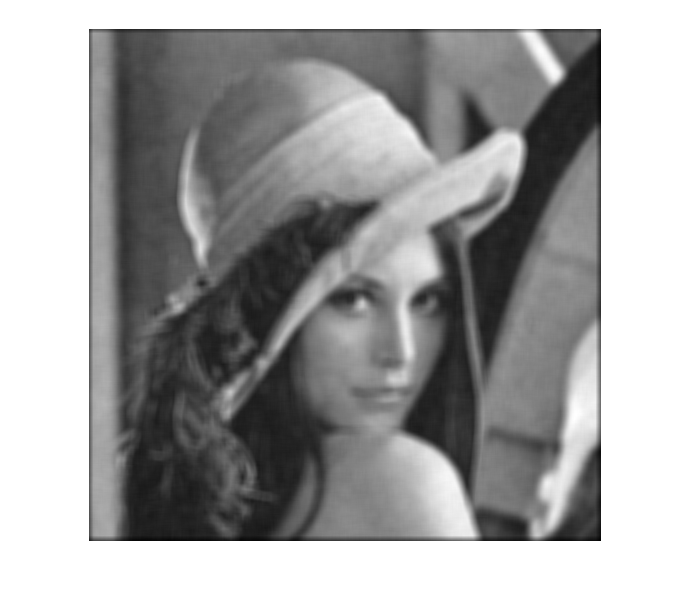


imshow(gp,[]);

### Frekvencni

tic();
F = fft2(f);
G = H1.*F;
gf=real(ifft2(G));
toc()

Elapsed time is 0.017965 seconds.


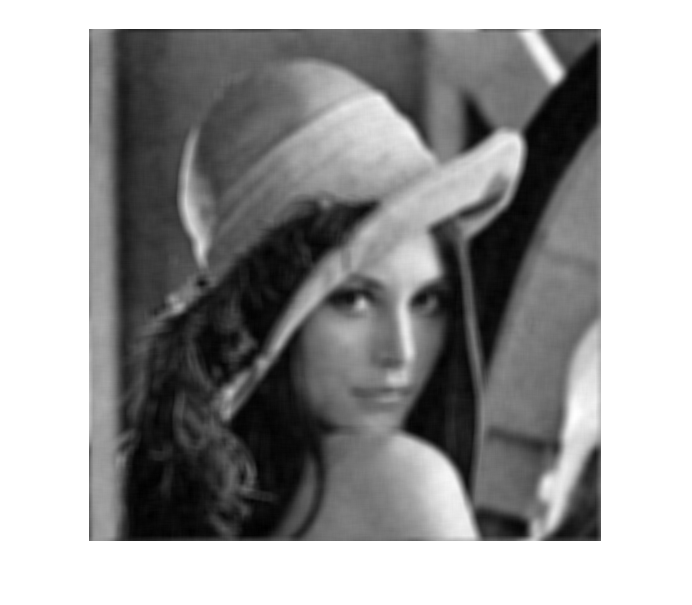


figure, imshow(gf,[]);

### Rozdil

d = abs(gp(10:end-10,10:end-10) - gf(10:end-10,10:end-10));

maximalni_rozdil = max(d(:)); % maximalni rozdil
display(maximalni_rozdil);

maximalni_rozdil = 1.4211e-13

minimalni_rozdil = min (d(:));
display(minimalni_rozdil);

minimalni_rozdil = 0